%Resistance of the power resitors in series that acted as the load.
R2 = 805 ;
R1 = 838+690 ;



Battery Voltage

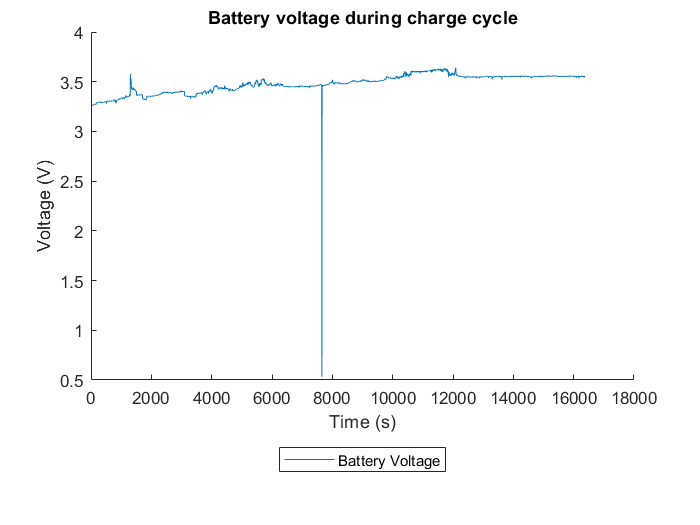

figure(1)
hold on 
%to convert from time adc reading to voltage
BatteryVoltage = (ADCReading)*(5/1023);
BatteryVoltageSeries = timeseries(BatteryVoltage,time/1000);
plot(BatteryVoltageSeries)


title("Battery voltage during charge cycle")
xlabel("Time (s)")
ylabel('Voltage (V)')

legend('Battery Voltage' )
 legend('Location','southoutside')

PV panel current and voltage

figure(2)
hold on


yyaxis left;
ylabel('Voltage (V)')

SolarVoltage = (ADCReading2)*(5/1023);
SolarVoltage = SolarVoltage *((R2+R1)/R2);
SolarVoltageSeries = timeseries(SolarVoltage,time/1000);
plot(SolarVoltageSeries)


yyaxis right;
ylabel('Current (A)')

InputCurrent = (ADCReading1)*(5/1023);
InputCurrent = InputCurrent/10; %This is the voltage but using V=IR with a one ohm resistor V=I(1) Therefore V=I
InputCurrentSeries = timeseries(InputCurrent,time/1000);
plot(InputCurrentSeries)

%the output voltage was not measured over the full resistance as this could
%cause the adc to saturate at 5V if the output went higher than 5V.
%To caluclated the full output voltage the voltage divider equation was used.
%This gives


title("PV panel Voltage and current during charge cycle")
xlabel("Time (s)")
legend('PV Voltage','PV current' )
 legend('Location','southoutside')
 hold off


PV power!         

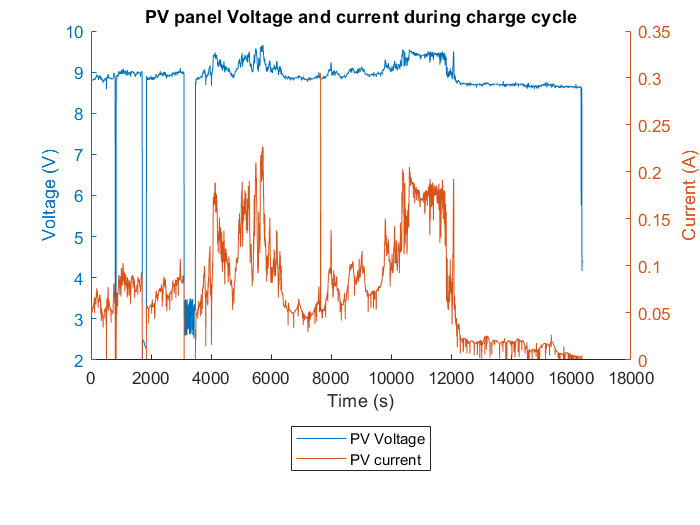

figure(3)
hold off

cla(gca,'reset')

yyaxis left
power = InputCurrent.*SolarVoltage + InputCurrent.^2*1 ; %The input current^2 *1 is to account for the power dissapated across the 1 ohm resistor. The power dissipated accross the 2.3Mohm voltage divider is neglegible for this testing.
powerSeries = timeseries(power, time/1000);
plot(powerSeries);

pave = mean(power)

pave = 0.6690

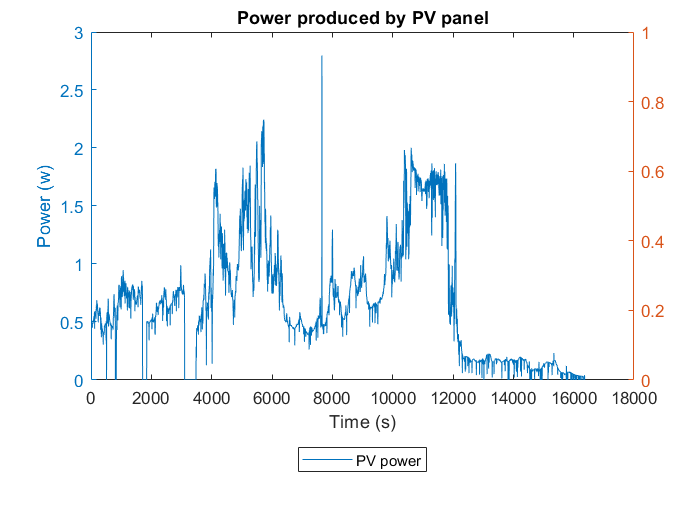




title("Power produced by PV panel")
ylabel('Power (w)')
xlabel("Time (s)")
legend('PV power' )
legend('Location','southoutside')



WattHours = trapz(1/720,power)

WattHours = 3.0436